# EL2520 Computer Exercise 4

## 3.1 | Static Decoupling

### 3.1.1 | Decouple the system

s = tf('s');
% sys = minphase;
sys = nonminphase;
% Remember to change omega_cd in 3.1.2 to correspond to sys

A = sys.A;
B = sys.B;
C = sys.C;
D = sys.D;

I = eye(size(A));
G = minreal(C*inv(s*I-A)*B+D); % 2x2 trans. func.
% g11 = G(1,1);
% g12 = G(1,2); % Input 2 to output 1
% g21 = G(2,1); % Input 1 to output 2
% g22 = G(2,2);

G_inv = minreal(inv(G));
W_1 = evalfr(G_inv,0);
W_2 = eye(size(G));

G_tilde = minreal(W_2*G*W_1)


G_tilde =
 
  From input 1 to output...
         -0.02872 s + 0.004382
   1:  -------------------------
       s^2 + 0.1369 s + 0.004382
 
         0.04787 s + 1.257e-09
   2:  -------------------------
       s^2 + 0.1378 s + 0.004265
 
  From input 2 to output...
         0.04399 s + 8.331e-15
   1:  -------------------------
       s^2 + 0.1369 s + 0.004382
 
         -0.02639 s + 0.004265
   2:  -------------------------
       s^2 + 0.1378 s + 0.004265
 
Continuous-time transfer function.



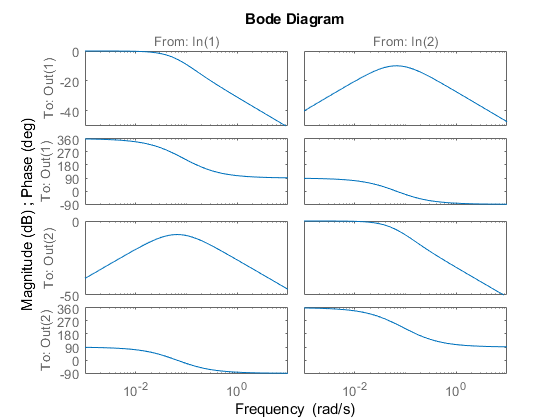

bode(G_tilde)


% RGA
rga = minreal(G*transpose(G_inv));
rga_zero = freqresp(rga,0)

rga_zero =     0.6806    0.2214
   -0.2086    1.4015


% Can use same coupling in controller F for minphase and nonminphase

### 3.1.2 | Design decoupled PI controller

% Given design criteria
p_m = pi/3; % phi_m [rad]
% w_cd = 0.1; % omega_c,d minphase [rad/s] 
w_cd = 0.02; % omega_c,d nonminphase [rad/s] 

g11 = G_tilde(1,1);
g22 = G_tilde(2,2);

[m11,p11] = bode(g11, w_cd); % Amplitude and phase of system at w_cd
[m22,p22] = bode(g22, w_cd); % Amplitude and phase of system at w_cd

T11 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p11)); 
T22 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p22));

l11 = g11*(1 + 1/(s*T11));
l22 = g22*(1 + 1/(s*T22));

[m1, p1] = bode(l11,w_cd);
[m2, p2] = bode(l22,w_cd);

K1 = 1/m1;
K2 = 1/m2;

f1 = K1*(1 + 1/(s*T11));
f2 = K2*(1 + 1/(s*T22));

F_tilde = minreal([f1, 0; 0, f2])


F_tilde =
 
  From input 1 to output...
       0.2269 s + 0.02139
   1:  ------------------
               s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.2401 s + 0.02156
   2:  ------------------
               s
 
Continuous-time transfer function.



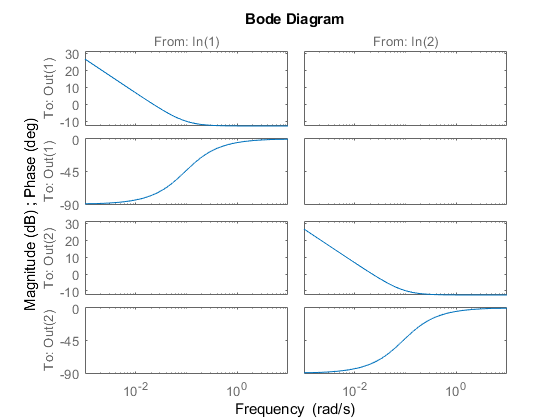

bode(F_tilde)

% F = inv(G(0))*F_tilde
F = minreal(W_1*F_tilde)


F =
 
  From input 1 to output...
       -0.3121 s - 0.02943
   1:  -------------------
                s
 
       0.6008 s + 0.05665
   2:  ------------------
               s
 
  From input 2 to output...
       0.5057 s + 0.04543
   1:  ------------------
               s
 
       -0.3505 s - 0.03149
   2:  -------------------
                s
 
Continuous-time transfer function.



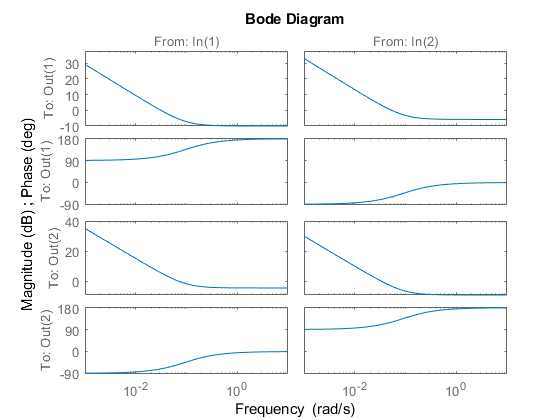

bode(F)

### 3.1.3 | Sensitivity & Complimentary Sensitivity

I = eye(size(G));
L = minreal(G*F);
S = minreal(inv(I + L));
T = minreal(S*L);

[Gm,Pm,wp,wc] = margin(L(1,1)) % Phase margin, amplitude margin, and corresp. freqs. of G_d

Gm = 6.8704

Pm = 60.0006

wp = 0.0836

wc = 0.0200

[Gm,Pm,wp,wc] = margin(L(2,2)) % Phase margin, amplitude margin, and corresp. freqs. of G_d

Gm = 7.5323

Pm = 60.0005

wp = 0.0877

wc = 0.0200

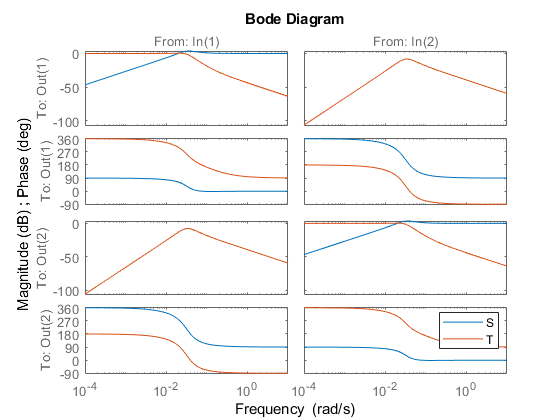


bode(S,T)
legend

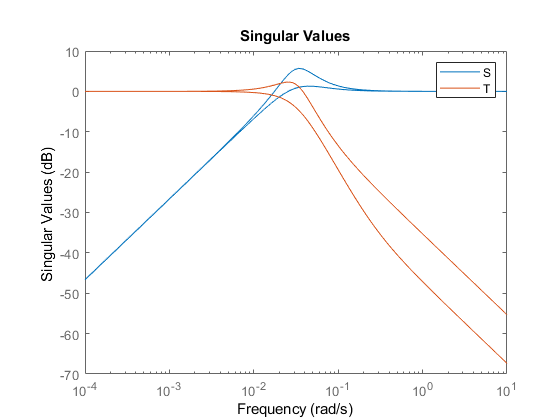

% Singular values
sigma(S, T)
legend

max(sigma(S),[],2)

ans =     1.9251
    1.1597


max(sigma(T),[],2)

ans =     1.3045
    0.9997


### 3.1.4 | Closed Loop Simulation

closedloop